# Actividad de cierre

Para la actividad de cierre se propone el siguiente robot a modelar.

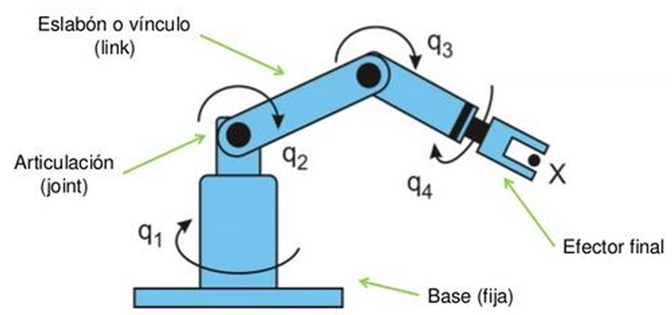

Las observacciones más importantes son los cambios del marco de referencia al pasar de q1 a q1, y de q3 a q4. 

clear all
close all
clc

%Declaración de variables simbólicas
syms th1(t) th2(t) th3(t) th4(t) t r l1 l2 l3 l4

%Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP=[0 0 0 0];

%Creamos el vector de coordenadas articulares
disp('Coordenadas generalizadas');

Coordenadas generalizadas


Q= [th1 th2 th3 th4]

$$Q(t) = \left(\begin{array}{cccc} {\mathrm{th}}_{1}\left(t\right) & {\mathrm{th}}_{2}\left(t\right) & {\mathrm{th}}_{3}\left(t\right) & {\mathrm{th}}_{4}\left(t\right) \end{array}\right)$$


%Creamos el vector de velocidades generalizadas
disp('Velocidades generalizadas');

Velocidades generalizadas


Qp= diff(Q, t)

$$Qp(t) = \left(\begin{array}{cccc} \frac{\partial }{\partial t}{\mathrm{th}}_{1}\left(t\right) & \frac{\partial }{\partial t}{\mathrm{th}}_{2}\left(t\right) & \frac{\partial }{\partial t}{\mathrm{th}}_{3}\left(t\right) & \frac{\partial }{\partial t}{\mathrm{th}}_{4}\left(t\right) \end{array}\right)$$


%Número de grado de libertad del robot
GDL= size(RP,2);
GDL_str= num2str(GDL);

Como podemos observar por el paso anterior se maneja un robot de 4 grados de libertad.

el marco inicial de referencia que se va a usar será el siguiente.

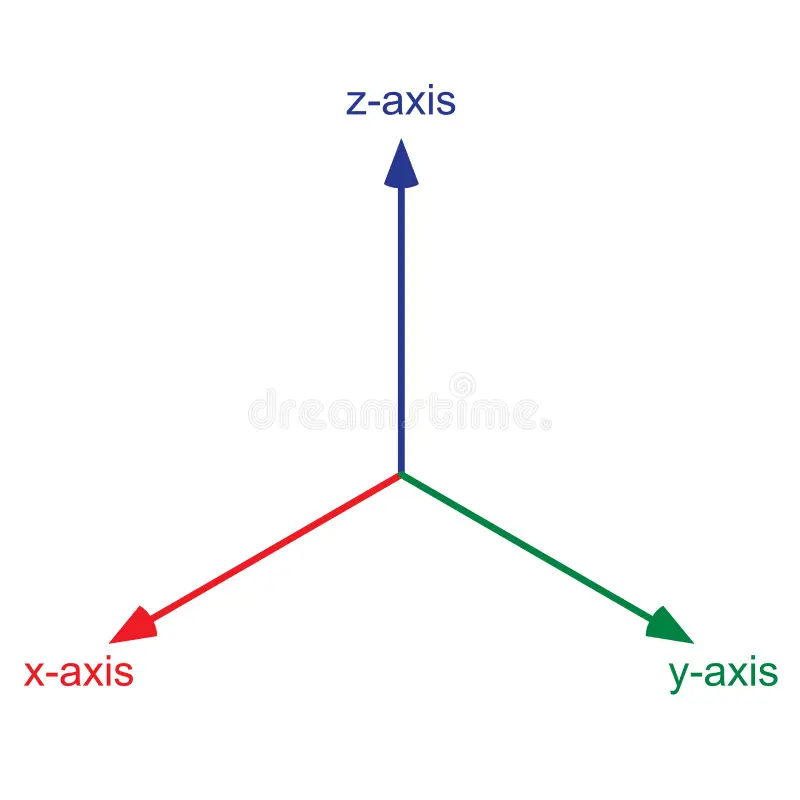

Donde z esta viendo para arriba y x hacia afuera del robot.

Para esto se inicializa la matriz de rotacion sobre el eje z. y la tranformacion para la cual se hace la rotacion en y.

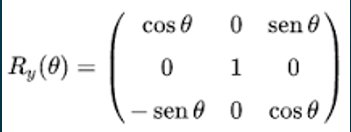

Esta se evalua en 90° para alinear la siguiente junta.

%Junta 1

%Rocacion de la junta sobre el eje z.
Rotz = [cos(th1) -sin(th1)  0;
        sin(th1)  cos(th1)  0;
        0         0         1];
%Rotación en y evaluada en 90° para la transformacion del marco de
%referencia.
Transy = [0 0 1
          0 1 0
         -1 0 0];
%Posición de la junta 1 respecto a 0
P(:,:,1)= [0; 0; l1];
%Matriz de rotación de la junta 1 respecto a 0
R(:,:,1)= Rotz*Transy;

Se continua con la segunda junta, debido a que la junta anterior tiene implicita la transformación solo se maneja la matriz de rotación en z, sobra la cual gira el segmento.

%Junta 2
%Posición de la junta 2 respecto a 0
P(:,:,2)= [l2*sin(th2); l2*cos(th2);0];
%Matriz de rotación de la junta 2 respecto a 0
R(:,:,2)= [cos(th2) -sin(th2)  0;
           sin(th2)  cos(th2)  0;
           0         0         1];

Ahora el marco sobre el cual esta la segunda junta es como el anterior, pero z giró 90° hacia x; por lo que en x esta z, x ve hacia abajo y y se queda como esta debido a que fue el eje sobre el cuál se giró. este marco de referencia es el mismo para la junta 3, solo que a este se le aplica una segunda transformacion.

Para lograr esto se gira el marco -90° sobre x.

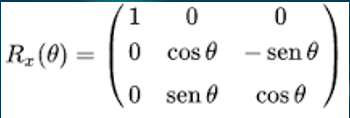

%Junta 3
%Rocacion de la junta sobre el eje z.
Rotz = [cos(th3) -sin(th3)  0;
        sin(th3)  cos(th3)  0;
        0         0         1];
%Rotación en y evaluada en 90° para la transformacion del marco de
%referencia.
Transx = [1  0 0
          0  0 1
          0 -1 0];
%Posición de la junta 3 respecto a 0
P(:,:,3)= [l3*sin(th3); l3*cos(th3);0];
%Matriz de rotación de la junta 1 respecto a 0
R(:,:,3)= Rotz*Transx;

Para la última junta despues de realizar el marco giró z hacia y en -90° sobre el eje de x.

por lo que ahora z esta en el lugar de y, x sigue viendo hacia abajo, y y estaría viendo hacia atras.

por lo que se hace el modelo de la siguiente junta.

%Junta 4
%Posición de la junta 4 respecto a 0
P(:,:,4)= [r; r; l4];
%Matriz de rotación de la junta 4 respecto a 0
R(:,:,4)= [cos(th4) -sin(th4)  0;
           sin(th4)  cos(th4)  0;
           0         0         1];

Se procede hacer el calculo de las velocidades 

%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 
%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 
%Inicializamos las INVERSAS de las matrices de rotación vistas desde el marco de referencia inercial
RO_inv(:,:,GDL)= R(:,:,GDL); 

for i = 1:GDL
    i_str= num2str(i);
    disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1])

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
    disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i)= simplify(T(:,:,i))

    RO(:,:,i)= T(1:3,1:3,i);
    RO_inv(:,:,i)= transpose(RO(:,:,i));
    PO(:,:,i)= T(1:3,4,i);
    %pretty(RO(:,:,i));
    %pretty(RO_inv(:,:,i));
    %pretty(PO(:,:,i));
end

Matriz de Transformación local A1


$$\left(\begin{array}{cccc} 0 & -\sin\left({\mathrm{th}}_{1}\left(t\right)\right) & \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & 0\\ 0 & \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & \sin\left({\mathrm{th}}_{1}\left(t\right)\right) & 0\\ -1 & 0 & 0 & l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

$$\left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

$$\left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{4}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{4}\left(t\right)\right) & 0 & 0\\ \sin\left({\mathrm{th}}_{4}\left(t\right)\right) & \cos\left({\mathrm{th}}_{4}\left(t\right)\right) & 0 & 0\\ 0 & 0 & 1 & l_{4}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Matriz de Transformación global T1


$$\left(\begin{array}{cccc} 0 & -\sin\left({\mathrm{th}}_{1}\left(t\right)\right) & \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & 0\\ 0 & \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & \sin\left({\mathrm{th}}_{1}\left(t\right)\right) & 0\\ -1 & 0 & 0 & l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

$$\left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

$$\left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{4}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{4}\left(t\right)\right) & 0 & 0\\ \sin\left({\mathrm{th}}_{4}\left(t\right)\right) & \cos\left({\mathrm{th}}_{4}\left(t\right)\right) & 0 & 0\\ 0 & 0 & 1 & l_{4}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Matriz de Transformación local A2


$$\left(\begin{array}{cccc} 0 & -\sin\left({\mathrm{th}}_{1}\left(t\right)\right) & \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & 0\\ 0 & \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & \sin\left({\mathrm{th}}_{1}\left(t\right)\right) & 0\\ -1 & 0 & 0 & l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{2}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{2}\left(t\right)\right) & 0 & l_{2}\,\cos\left({\mathrm{th}}_{2}\left(t\right)\right)\\ \sin\left({\mathrm{th}}_{2}\left(t\right)\right) & \cos\left({\mathrm{th}}_{2}\left(t\right)\right) & 0 & l_{2}\,\sin\left({\mathrm{th}}_{2}\left(t\right)\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

$$\left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{4}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{4}\left(t\right)\right) & 0 & 0\\ \sin\left({\mathrm{th}}_{4}\left(t\right)\right) & \cos\left({\mathrm{th}}_{4}\left(t\right)\right) & 0 & 0\\ 0 & 0 & 1 & l_{4}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Matriz de Transformación global T2


$$\left(\begin{array}{cccc} 0 & -\sin\left({\mathrm{th}}_{1}\left(t\right)\right) & \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & 0\\ 0 & \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & \sin\left({\mathrm{th}}_{1}\left(t\right)\right) & 0\\ -1 & 0 & 0 & l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} -\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sin\left({\mathrm{th}}_{2}\left(t\right)\right) & -\cos\left({\mathrm{th}}_{2}\left(t\right)\right)\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right) & \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & -l_{2}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sin\left({\mathrm{th}}_{2}\left(t\right)\right)\\ \cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sin\left({\mathrm{th}}_{2}\left(t\right)\right) & \cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\cos\left({\mathrm{th}}_{2}\left(t\right)\right) & \sin\left({\mathrm{th}}_{1}\left(t\right)\right) & l_{2}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sin\left({\mathrm{th}}_{2}\left(t\right)\right)\\ -\cos\left({\mathrm{th}}_{2}\left(t\right)\right) & \sin\left({\mathrm{th}}_{2}\left(t\right)\right) & 0 & l_{1}-l_{2}\,\cos\left({\mathrm{th}}_{2}\left(t\right)\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

$$\left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{4}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{4}\left(t\right)\right) & 0 & 0\\ \sin\left({\mathrm{th}}_{4}\left(t\right)\right) & \cos\left({\mathrm{th}}_{4}\left(t\right)\right) & 0 & 0\\ 0 & 0 & 1 & l_{4}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Matriz de Transformación local A3


$$\left(\begin{array}{cccc} 0 & -\sin\left({\mathrm{th}}_{1}\left(t\right)\right) & \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & 0\\ 0 & \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & \sin\left({\mathrm{th}}_{1}\left(t\right)\right) & 0\\ -1 & 0 & 0 & l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{2}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{2}\left(t\right)\right) & 0 & l_{2}\,\cos\left({\mathrm{th}}_{2}\left(t\right)\right)\\ \sin\left({\mathrm{th}}_{2}\left(t\right)\right) & \cos\left({\mathrm{th}}_{2}\left(t\right)\right) & 0 & l_{2}\,\sin\left({\mathrm{th}}_{2}\left(t\right)\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{3}\left(t\right)\right) & 0 & -\sin\left({\mathrm{th}}_{3}\left(t\right)\right) & l_{3}\,\cos\left({\mathrm{th}}_{3}\left(t\right)\right)\\ \sin\left({\mathrm{th}}_{3}\left(t\right)\right) & 0 & \cos\left({\mathrm{th}}_{3}\left(t\right)\right) & l_{3}\,\sin\left({\mathrm{th}}_{3}\left(t\right)\right)\\ 0 & -1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{4}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{4}\left(t\right)\right) & 0 & 0\\ \sin\left({\mathrm{th}}_{4}\left(t\right)\right) & \cos\left({\mathrm{th}}_{4}\left(t\right)\right) & 0 & 0\\ 0 & 0 & 1 & l_{4}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Matriz de Transformación global T3


$$\left(\begin{array}{cccc} 0 & -\sin\left({\mathrm{th}}_{1}\left(t\right)\right) & \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & 0\\ 0 & \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & \sin\left({\mathrm{th}}_{1}\left(t\right)\right) & 0\\ -1 & 0 & 0 & l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} -\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sin\left({\mathrm{th}}_{2}\left(t\right)\right) & -\cos\left({\mathrm{th}}_{2}\left(t\right)\right)\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right) & \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & -l_{2}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sin\left({\mathrm{th}}_{2}\left(t\right)\right)\\ \cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sin\left({\mathrm{th}}_{2}\left(t\right)\right) & \cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\cos\left({\mathrm{th}}_{2}\left(t\right)\right) & \sin\left({\mathrm{th}}_{1}\left(t\right)\right) & l_{2}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sin\left({\mathrm{th}}_{2}\left(t\right)\right)\\ -\cos\left({\mathrm{th}}_{2}\left(t\right)\right) & \sin\left({\mathrm{th}}_{2}\left(t\right)\right) & 0 & l_{1}-l_{2}\,\cos\left({\mathrm{th}}_{2}\left(t\right)\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\begin{array}{l} \left(\begin{array}{cccc} -\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sin\left(\sigma_{2}\right) & -\cos\left({\mathrm{th}}_{1}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,\cos\left(\sigma_{2}\right) & -\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sigma_{1}\\ \cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sin\left(\sigma_{2}\right) & -\sin\left({\mathrm{th}}_{1}\left(t\right)\right) & \cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\cos\left(\sigma_{2}\right) & \cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sigma_{1}\\ -\cos\left(\sigma_{2}\right) & 0 & \sin\left(\sigma_{2}\right) & l_{1}-l_{2}\,\cos\left({\mathrm{th}}_{2}\left(t\right)\right)-l_{3}\,\cos\left(\sigma_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{2}\,\sin\left({\mathrm{th}}_{2}\left(t\right)\right)+l_{3}\,\sin\left(\sigma_{2}\right)\\ \sigma_{2}={\mathrm{th}}_{2}\left(t\right)+{\mathrm{th}}_{3}\left(t\right) \end{array}$$

$$\left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{4}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{4}\left(t\right)\right) & 0 & 0\\ \sin\left({\mathrm{th}}_{4}\left(t\right)\right) & \cos\left({\mathrm{th}}_{4}\left(t\right)\right) & 0 & 0\\ 0 & 0 & 1 & l_{4}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Matriz de Transformación local A4


$$\left(\begin{array}{cccc} 0 & -\sin\left({\mathrm{th}}_{1}\left(t\right)\right) & \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & 0\\ 0 & \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & \sin\left({\mathrm{th}}_{1}\left(t\right)\right) & 0\\ -1 & 0 & 0 & l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{2}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{2}\left(t\right)\right) & 0 & l_{2}\,\cos\left({\mathrm{th}}_{2}\left(t\right)\right)\\ \sin\left({\mathrm{th}}_{2}\left(t\right)\right) & \cos\left({\mathrm{th}}_{2}\left(t\right)\right) & 0 & l_{2}\,\sin\left({\mathrm{th}}_{2}\left(t\right)\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{3}\left(t\right)\right) & 0 & -\sin\left({\mathrm{th}}_{3}\left(t\right)\right) & l_{3}\,\cos\left({\mathrm{th}}_{3}\left(t\right)\right)\\ \sin\left({\mathrm{th}}_{3}\left(t\right)\right) & 0 & \cos\left({\mathrm{th}}_{3}\left(t\right)\right) & l_{3}\,\sin\left({\mathrm{th}}_{3}\left(t\right)\right)\\ 0 & -1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{4}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{4}\left(t\right)\right) & 0 & 0\\ \sin\left({\mathrm{th}}_{4}\left(t\right)\right) & \cos\left({\mathrm{th}}_{4}\left(t\right)\right) & 0 & 0\\ 0 & 0 & 1 & l_{4}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Matriz de Transformación global T4


$$\left(\begin{array}{cccc} 0 & -\sin\left({\mathrm{th}}_{1}\left(t\right)\right) & \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & 0\\ 0 & \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & \sin\left({\mathrm{th}}_{1}\left(t\right)\right) & 0\\ -1 & 0 & 0 & l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} -\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sin\left({\mathrm{th}}_{2}\left(t\right)\right) & -\cos\left({\mathrm{th}}_{2}\left(t\right)\right)\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right) & \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & -l_{2}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sin\left({\mathrm{th}}_{2}\left(t\right)\right)\\ \cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sin\left({\mathrm{th}}_{2}\left(t\right)\right) & \cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\cos\left({\mathrm{th}}_{2}\left(t\right)\right) & \sin\left({\mathrm{th}}_{1}\left(t\right)\right) & l_{2}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sin\left({\mathrm{th}}_{2}\left(t\right)\right)\\ -\cos\left({\mathrm{th}}_{2}\left(t\right)\right) & \sin\left({\mathrm{th}}_{2}\left(t\right)\right) & 0 & l_{1}-l_{2}\,\cos\left({\mathrm{th}}_{2}\left(t\right)\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\begin{array}{l} \left(\begin{array}{cccc} -\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sin\left(\sigma_{2}\right) & -\cos\left({\mathrm{th}}_{1}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,\cos\left(\sigma_{2}\right) & -\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sigma_{1}\\ \cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sin\left(\sigma_{2}\right) & -\sin\left({\mathrm{th}}_{1}\left(t\right)\right) & \cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\cos\left(\sigma_{2}\right) & \cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sigma_{1}\\ -\cos\left(\sigma_{2}\right) & 0 & \sin\left(\sigma_{2}\right) & l_{1}-l_{2}\,\cos\left({\mathrm{th}}_{2}\left(t\right)\right)-l_{3}\,\cos\left(\sigma_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{2}\,\sin\left({\mathrm{th}}_{2}\left(t\right)\right)+l_{3}\,\sin\left(\sigma_{2}\right)\\ \sigma_{2}={\mathrm{th}}_{2}\left(t\right)+{\mathrm{th}}_{3}\left(t\right) \end{array}$$

$$\begin{array}{l} \left(\begin{array}{cccc} -\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sin\left({\mathrm{th}}_{4}\left(t\right)\right)-\cos\left({\mathrm{th}}_{4}\left(t\right)\right)\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sin\left(\sigma_{2}\right) & \sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sin\left({\mathrm{th}}_{4}\left(t\right)\right)\,\sin\left(\sigma_{2}\right)-\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\cos\left({\mathrm{th}}_{4}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,\cos\left(\sigma_{2}\right) & -\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sigma_{1}-l_{4}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,\cos\left(\sigma_{2}\right)\\ \cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\cos\left({\mathrm{th}}_{4}\left(t\right)\right)\,\sin\left(\sigma_{2}\right)-\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sin\left({\mathrm{th}}_{4}\left(t\right)\right) & -\cos\left({\mathrm{th}}_{4}\left(t\right)\right)\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)-\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sin\left({\mathrm{th}}_{4}\left(t\right)\right)\,\sin\left(\sigma_{2}\right) & \cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\cos\left(\sigma_{2}\right) & \cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sigma_{1}+l_{4}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\cos\left(\sigma_{2}\right)\\ -\cos\left({\mathrm{th}}_{4}\left(t\right)\right)\,\cos\left(\sigma_{2}\right) & \sin\left({\mathrm{th}}_{4}\left(t\right)\right)\,\cos\left(\sigma_{2}\right) & \sin\left(\sigma_{2}\right) & l_{1}-l_{2}\,\cos\left({\mathrm{th}}_{2}\left(t\right)\right)-l_{3}\,\cos\left(\sigma_{2}\right)+l_{4}\,\sin\left(\sigma_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{2}\,\sin\left({\mathrm{th}}_{2}\left(t\right)\right)+l_{3}\,\sin\left(\sigma_{2}\right)\\ \sigma_{2}={\mathrm{th}}_{2}\left(t\right)+{\mathrm{th}}_{3}\left(t\right) \end{array}$$

Calculo de las matrices homogeneas globales

%Calculamos el jacobiano lineal de forma analítica
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));
            Jw_a(:,k)=[0,0,1];
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    


disp('Jacobiano lineal obtenido de forma analítica');

Jacobiano lineal obtenido de forma analítica


Jv_a= simplify (Jv_a)

$$Jv\_a = \begin{array}{l} \left(\begin{array}{cccc} -\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sigma_{3}-l_{4}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\cos\left(\sigma_{5}\right) & -\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sigma_{1} & -\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sigma_{2} & 0\\ -\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sigma_{3}-l_{4}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,\cos\left(\sigma_{5}\right) & \cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sigma_{1} & \cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sigma_{2} & 0\\ 0 & \sigma_{4}+l_{4}\,\cos\left(\sigma_{5}\right)+l_{3}\,\sin\left(\sigma_{5}\right) & l_{4}\,\cos\left(\sigma_{5}\right)+l_{3}\,\sin\left(\sigma_{5}\right) & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{2}\,\cos\left({\mathrm{th}}_{2}\left(t\right)\right)+l_{3}\,\cos\left(\sigma_{5}\right)-l_{4}\,\sin\left(\sigma_{5}\right)\\ \sigma_{2}=l_{3}\,\cos\left(\sigma_{5}\right)-l_{4}\,\sin\left(\sigma_{5}\right)\\ \sigma_{3}=\sigma_{4}+l_{3}\,\sin\left(\sigma_{5}\right)\\ \sigma_{4}=l_{2}\,\sin\left({\mathrm{th}}_{2}\left(t\right)\right)\\ \sigma_{5}={\mathrm{th}}_{2}\left(t\right)+{\mathrm{th}}_{3}\left(t\right) \end{array}$$

disp('Jacobiano ángular obtenido de forma analítica');

Jacobiano ángular obtenido de forma analítica


Jw_a= simplify (Jw_a)

$$Jw\_a = \left(\begin{array}{cccc} 0 & \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,\cos\left({\mathrm{th}}_{2}\left(t\right)+{\mathrm{th}}_{3}\left(t\right)\right)\\ 0 & \sin\left({\mathrm{th}}_{1}\left(t\right)\right) & \sin\left({\mathrm{th}}_{1}\left(t\right)\right) & \cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\cos\left({\mathrm{th}}_{2}\left(t\right)+{\mathrm{th}}_{3}\left(t\right)\right)\\ 1 & 0 & 0 & \sin\left({\mathrm{th}}_{2}\left(t\right)+{\mathrm{th}}_{3}\left(t\right)\right) \end{array}\right)$$



disp('Velocidad lineal obtenida mediante el Jacobiano lineal');

Velocidad lineal obtenida mediante el Jacobiano lineal


V=simplify (Jv_a*Qp')

$$V(t) = \begin{array}{l} \left(\begin{array}{c} -\sigma_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,\left(\sigma_{8}-\sigma_{7}\right)-\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{1}\left(t\right)}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sigma_{3}-\sigma_{2}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sigma_{4}\\ \sigma_{2}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sigma_{4}-\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{1}\left(t\right)}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sigma_{3}+\sigma_{1}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\left(\sigma_{8}-\sigma_{7}\right)\\ \sigma_{1}\,\left(\sigma_{6}+\sigma_{5}\right)+\sigma_{2}\,\sigma_{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{3}\left(t\right)}\\ \sigma_{2}=\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{2}\left(t\right)}\\ \sigma_{3}=l_{2}\,\sin\left({\mathrm{th}}_{2}\left(t\right)\right)+\sigma_{6}+\sigma_{5}\\ \sigma_{4}=l_{2}\,\cos\left({\mathrm{th}}_{2}\left(t\right)\right)+\sigma_{8}-\sigma_{7}\\ \sigma_{5}=l_{3}\,\sin\left({\mathrm{th}}_{2}\left(t\right)+{\mathrm{th}}_{3}\left(t\right)\right)\\ \sigma_{6}=l_{4}\,\cos\left({\mathrm{th}}_{2}\left(t\right)+{\mathrm{th}}_{3}\left(t\right)\right)\\ \sigma_{7}=l_{4}\,\sin\left({\mathrm{th}}_{2}\left(t\right)+{\mathrm{th}}_{3}\left(t\right)\right)\\ \sigma_{8}=l_{3}\,\cos\left({\mathrm{th}}_{2}\left(t\right)+{\mathrm{th}}_{3}\left(t\right)\right) \end{array}$$

disp('Velocidad angular obtenida mediante el Jacobiano angular');

Velocidad angular obtenida mediante el Jacobiano angular


W=simplify (Jw_a*Qp')

$$W(t) = \begin{array}{l} \left(\begin{array}{c} \sigma_{4}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)+\sigma_{3}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)-\sigma_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,\cos\left(\sigma_{2}\right)\\ \sigma_{4}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)+\sigma_{3}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)+\sigma_{1}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\cos\left(\sigma_{2}\right)\\ \bar{\frac{\partial }{\partial t}{\mathrm{th}}_{1}\left(t\right)}+\sigma_{1}\,\sin\left(\sigma_{2}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{4}\left(t\right)}\\ \sigma_{2}={\mathrm{th}}_{2}\left(t\right)+{\mathrm{th}}_{3}\left(t\right)\\ \sigma_{3}=\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{3}\left(t\right)}\\ \sigma_{4}=\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{2}\left(t\right)} \end{array}$$

Calculo de velocidades y jacobiano analitico